# **Final Project - Adaptive Cruise Control Model**

**Gurpo 1**: Adaptive Cruise Control 

**Authors:** Gabriel Lopes Lomeu Reis Oliveira;  Leonardo de Melo Abreu Lucas de Carvalho Sobral; Matheus Henrique de Souza Passos; Vitor Fassanaro Cortez de Carvalho.

This code demonstrates how adaptive cruise control was modeled for the final project of the technology residency.

The goal is to have an ego car travel at a speed chosen by the user or automatically adjust its speed to match the vehicle ahead while maintaining a safe distance between vehicles. This is achieved by controlling longitudinal acceleration.

## **Adaptive Cruise Control System**

The Adaptive Cruise Control (ACC) system is a technology developed to assist vehicles in maintaining a safe distance from other cars and staying within established speed limits. A car equipped with the ACC system (ego car) uses sensors to assess the relative distance ($D_{rel}$) and relative velocity ($V_{rel}$)  in relation to the vehicle ahead. The purpose of the ACC system is to maintain a desired cruise speed ($V_{set}$) or preserve a relative safe distance ($D_{safe}$) from the car in front. The change in the control objective is determined based on the following conditions.

- If $D_{rel} > D_{safe}$, the ACC system follows the desired reference cruise velocity commanded by the driver;

- If $D_{rel} < D_{safe}$, the ACC system controls the relative position of the ego car with respect to the lead car.

## **Adaptive Cruise Control Arquiteture**

The model produced by the team was constructed based on the requirements document, all system inputs and outputs can be observed in the image below. Our Adaptive Cruise Control (ACC) block, called “Ego ACC” has a input that consist of a bus containing eight signals, them being: the ACC control button, used to turn on this ADAS (Advanced Driver Assistance Systems) functionality, rain sensor, gas and brake pedal detection sensor, a signal containing information about any fault occurrence in any sensor necessary for the operation of the system, a velocity set by the driver, the relative distance between the car and any object detected by the distance sensor e the velocity of the vehicle at the moment. And as the output, the ACC block calculates the necessary acceleration needed to maintain the set speed or a safe distance to an object within range. The presence of the gas and brake pedal, and the occurrence of faults can be simulated with the toggle switches.

In the "Enviroment" block we have a model to check the functionality of our ACC system, in this block we have two models for vehicles, the Lead and Ego car. The Ego car is controlled by the ACC system and the Lead car has its acceleration using a sine to represent a car changing its velocity constantly during the simulation.

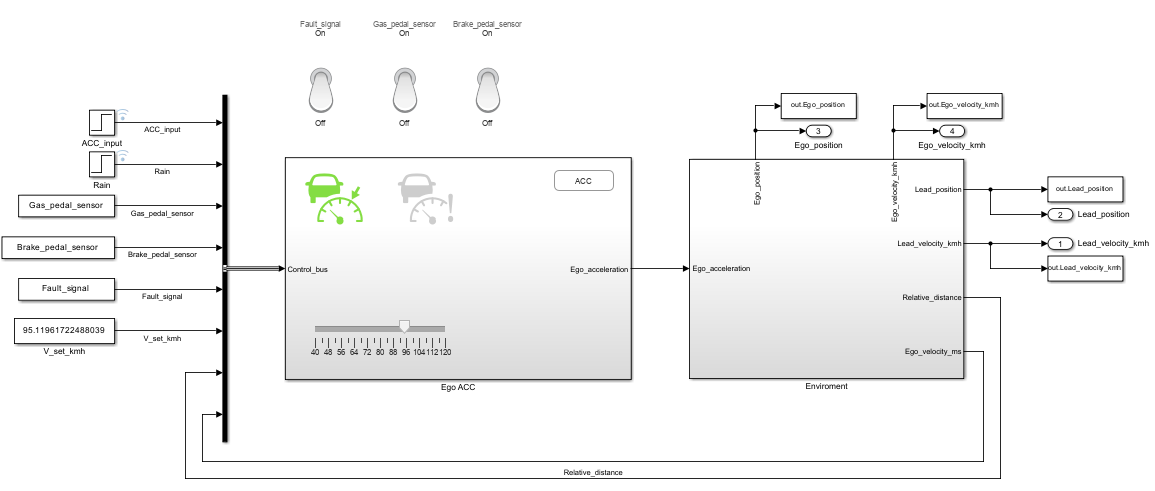

The “Logic Block” is responsible for enabling, turning on and off the ACC system, and doubling the time gap in the occurrence of rain. It’s composed of two State Flow blocks, the “ACC Action” block is used to check if the driver can use the ACC system and turn it on and off. And the “Rain Sensor” is used to read the message from the rain sensor. The control block is responsible for calculating the acceleration necessary to maintain the set velocity or a safe distance in the case of an object detected by the distance sensor. The block has two control loops, the acceleration is calculated in either one of them depending on the situation, if the safe distance is higher than the relative one the block enters in the “Control Distance Loop”, else it enters the “Control Speed Loop”.

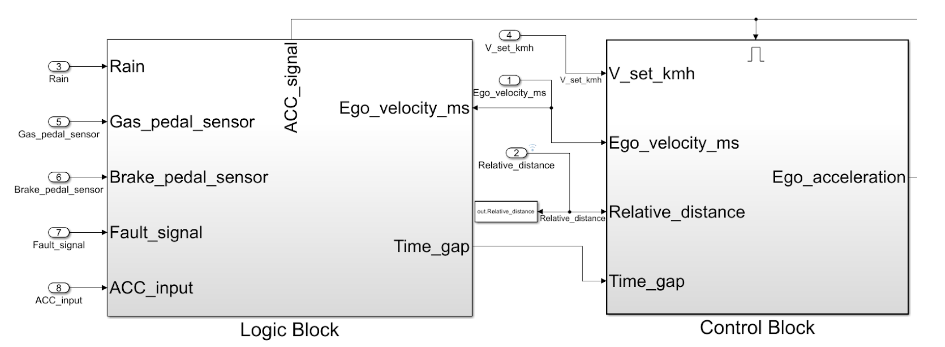

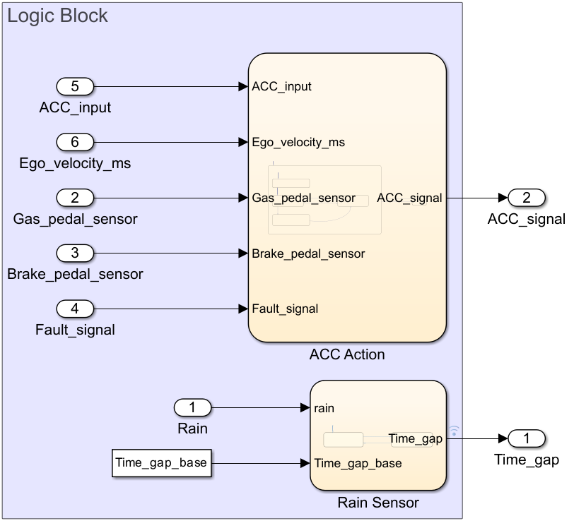

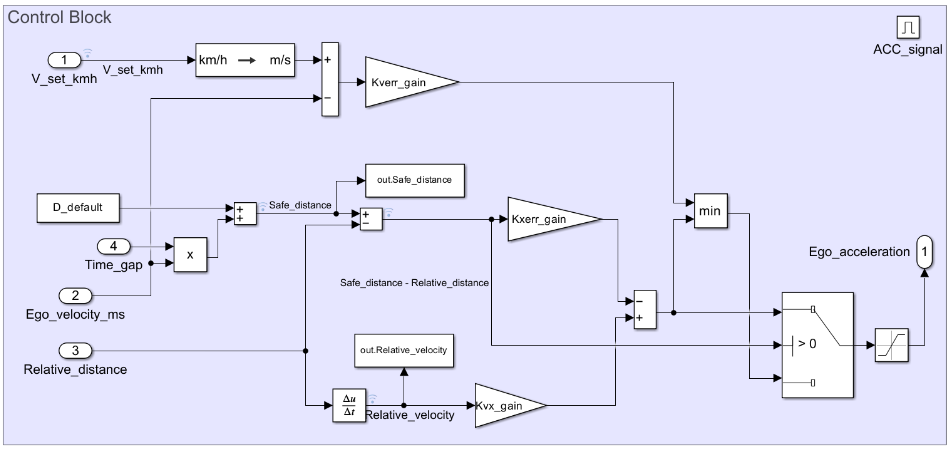

Opening the 'Environment' block we have a model to check the functionality of our ACC system, in this block we have two models for vehicles, the Lead and Ego car. The Ego car is controlled by the ACC system and the Lead car has its acceleration using a sine to represent a car changing its velocity constantly during the simulation.

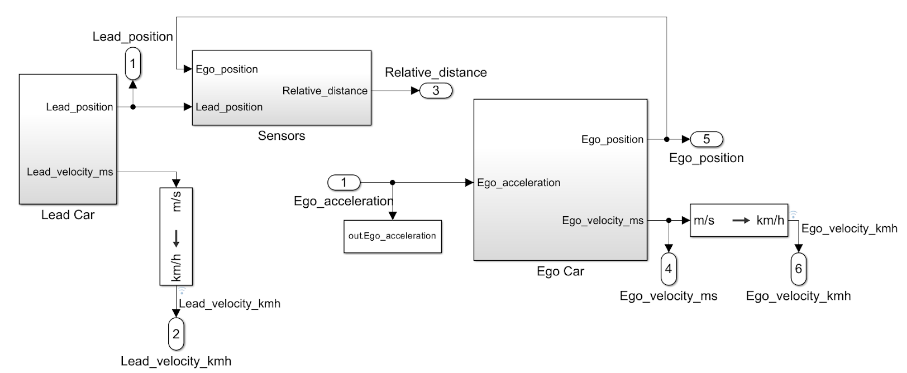

**Simulation times**

Ts = 0.01;  % Sample time.............................(s)   
Tf = 2000;  % Duration................................(s)

**Configuration of parameters for the ACC**

D_default            = 10;   % Default spacing.........................(m)
Time_gap_base        = 3;    % Time gap................................(s)
Ego_acceleration_min = -5;   % Minimum acceleration for driver comfort (m/s^2)
Ego_acceleration_max = 1.47; % Maximum acceleration for driver comfort (m/s^2)

%Gain values
Kverr_gain = 0.5; % ACC velocity error gain.................(N/A)
Kxerr_gain = 0.2; % ACC spacing error gain..................(N/A)
Kvx_gain   = 0.04; % ACC relative velocity gain.............(N/A)

%External Variables
m                  = 0.5;   % Constant for the transfer function of the car model     
b                  = 1;     % Constant for the transfer function of the car model   
Fault_signal       = false; % When "1" system failure, when "0" system is operatinal
Gas_pedal_sensor   = false; % When "0" pedal not pressed, when "1" pedal pressed
Brake_pedal_sensor = false; % When "0" pedal not pressed, when "1" pedal pressed

**Inicial position for lead car and ego car**

Lead_position_initial = 50;  % Initial lead car position (m)
Ego_position_initial  = 10;  % Initial ego car position..(m)

**Inicial velocity for lead car and ego car**

Lead_velocity_initial_kmh = 90; % Initial lead car position (Km/h)
Ego_velocity_initial_kmh  = 70; % Initial ego car position..(Km/h)

**Simulink model**

model= 'ACC';
open_system(model);
%Run the simulation
out = sim(model);

**Results **

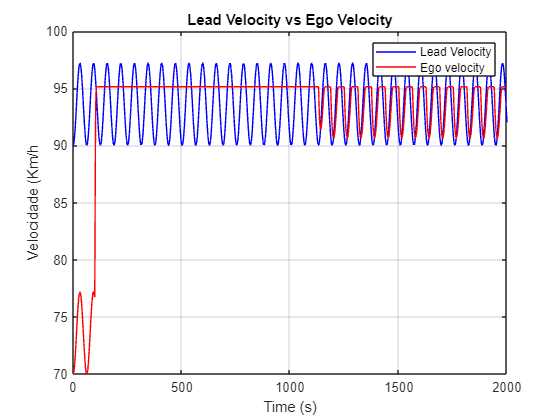

%Create plot of Lead_velocity vs Ego_velocity
figure;
plot(out.Lead_velocity_kmh.time,out.Lead_velocity_kmh.Data,'b',out.Ego_velocity_kmh.time,out.Ego_velocity_kmh.Data,'r');
% Add xlabel, ylabel, title, and legend
xlabel('Time (s)');
ylabel('Velocidade (Km/h');
title('Lead Velocity vs Ego Velocity');
legend('Lead Velocity', 'Ego velocity');
grid on;

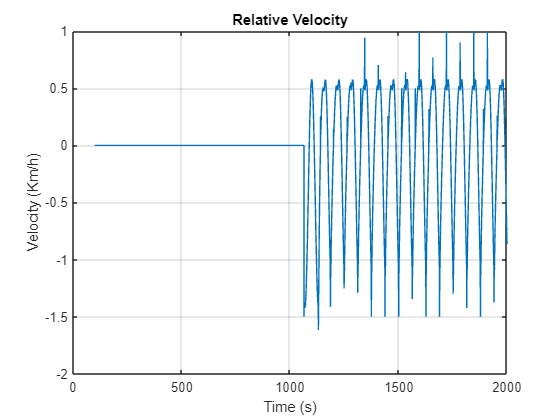

%Create plot of Relative_velocity
figure;
plot(out.Relative_velocity);
% Add xlabel, ylabel, title, and legend
xlabel('Time (s)');
ylabel('Velocity (Km/h)');
title('Relative Velocity');
grid on;

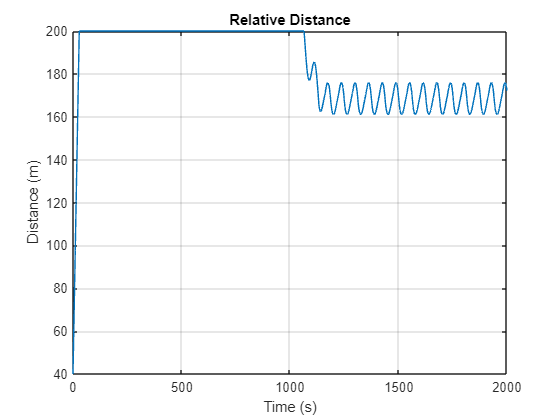

%Create plot of Relative_distance
figure;
plot(out.Relative_distance);
% Add xlabel, ylabel, title, and legend
xlabel('Time (s)');
ylabel('Distance (m)');
title('Relative Distance');
grid on;

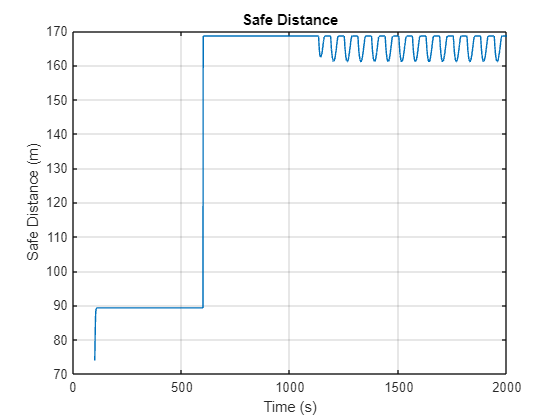

%Create plot of Safe_distance
figure;
plot(out.Safe_distance);
% Add xlabel, ylabel, title, and legend
xlabel('Time (s)');
ylabel('Safe Distance (m)');
title('Safe Distance');
grid on;

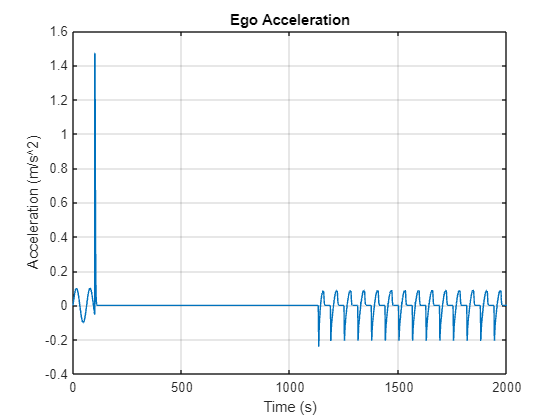

%Create plot of Ego_acceleration
figure;
plot(out.Ego_acceleration);
% Add xlabel, ylabel, title, and legend
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
title('Ego Acceleration');
grid on;